# Week 2: Rigid Motions

#### Author: Keith Chester

#### E-mail: kchester@wpi.edu

## Introduction

In the second week of *RBE 500 - Foundations of Robotics*, our material covered Chapter 2 of the book *Robot Modeling and Control* *(2nd edition)*. To this end, our assignment this week presents questions aiming to demonstrate understanding of rotation and homogenous transformation matricies. Our final question combines this information by analyzing an industrial robot as if we were considering it for real applications, and ensuring that we can model its motion using these techniques.

### II-1: Rotation Composition

Our first problem is a demonstration of understanding rotation composition - specificaly denoting the differences between fixed frame and current frame, as well as understanding three dimensional rotation matricies.

### II-2: Homogenous Transformations

Our second problem asks us to derive visually a series of homogenous transforms to convert between various coordinate frames. In turn, we must then prove that a calculated transform between our initial and final states is equivalent to calculating the chain of homogenous transforms.

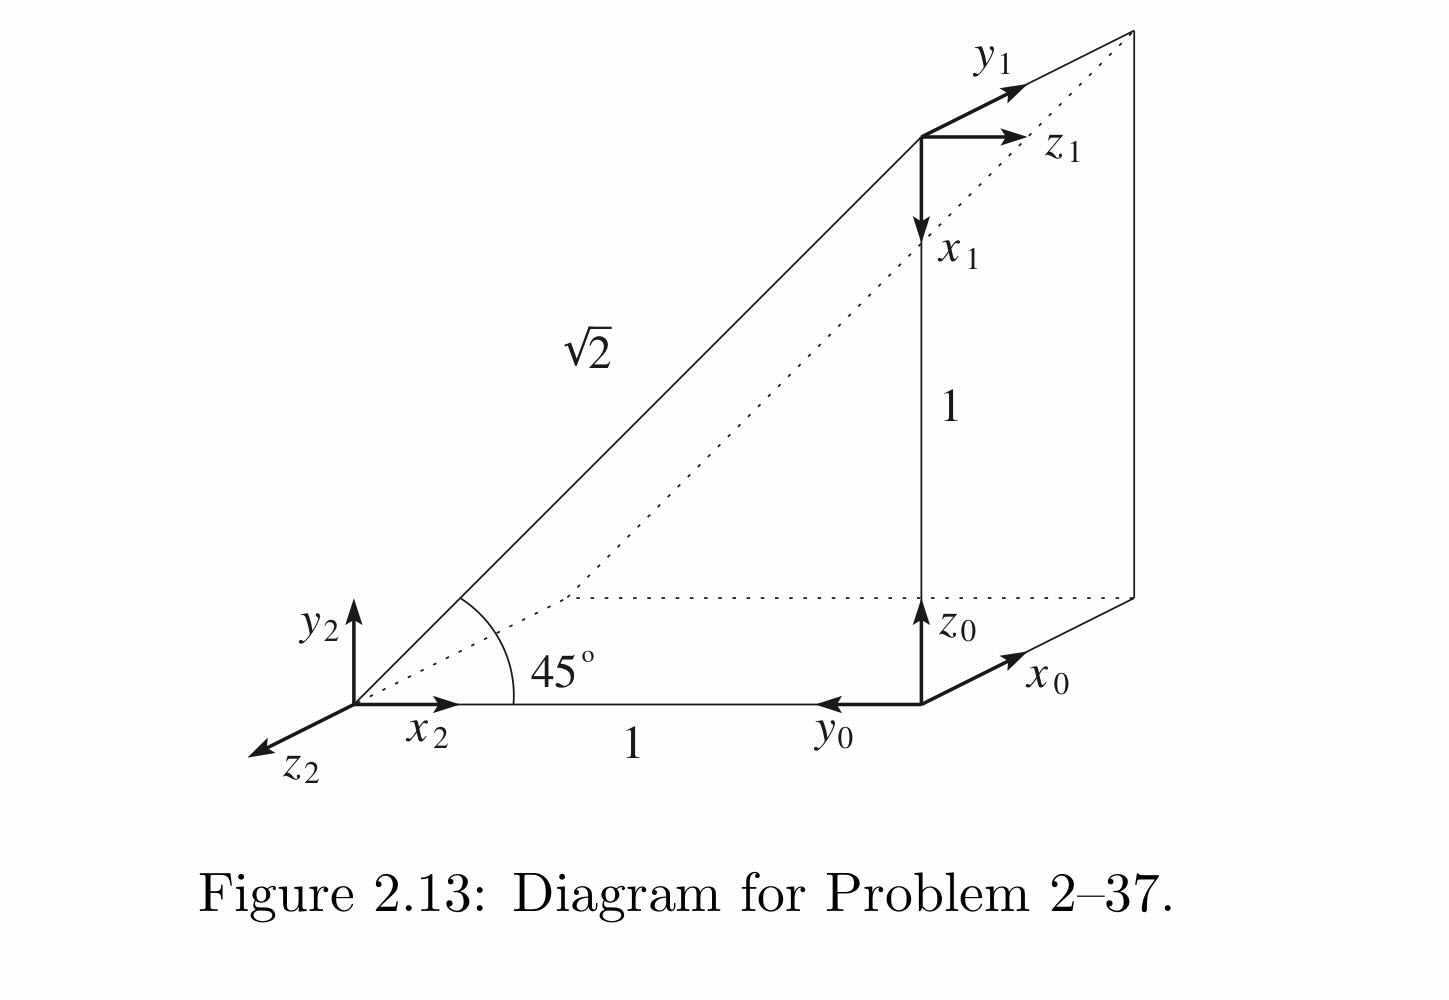

*Figure 1: from Robot Modeling and Control, 2nd edition, page 72*

From the figure above, we aim to determine the homogenous transformation from frame 0 (*x0y0z0*) to frame 1 (*x1y1z1*)*, *and then from frame 1 to frame 2 (*x2y2z2*). We must then show that 


$$H_2^0 =H_1^0 *H_2^1$$


### II-3: Denso HSR Robot

To apply our learned skills to a real-life problem, we aim to shop for a robotic arm. We will be looking at the Densor HSR Robot (an *RRP* arm) and analyzing its movement as if we were determining if it would fit for our application.

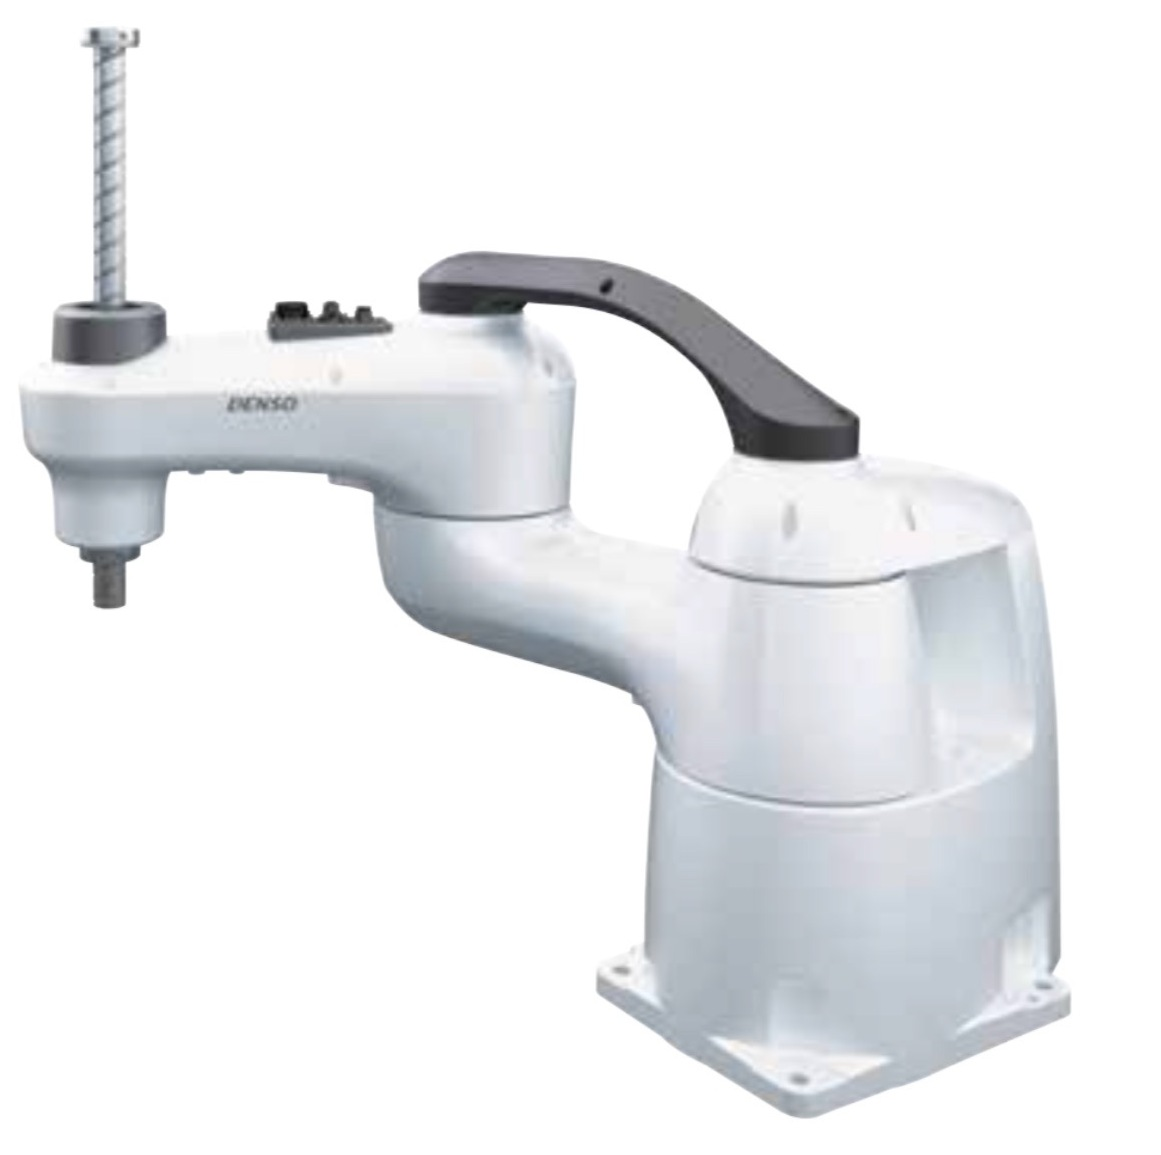

*Figure 2: Denso HSR Robot from product catalog*

For this analysis, we will be utilizing information provided in Denso's sales catalog - specifically key measurements of the arm of our specified model, the *480mm *reach configuration. From these measurements we are to plot the movement of the end-effector as its joints perform specified deltas in their positions.

## Methods

In this section we'll be discussing how we will be approaching and calculating each presented problem.

### II-1: Rotation Composition

Our problem, stated again with coloration to help track our work:

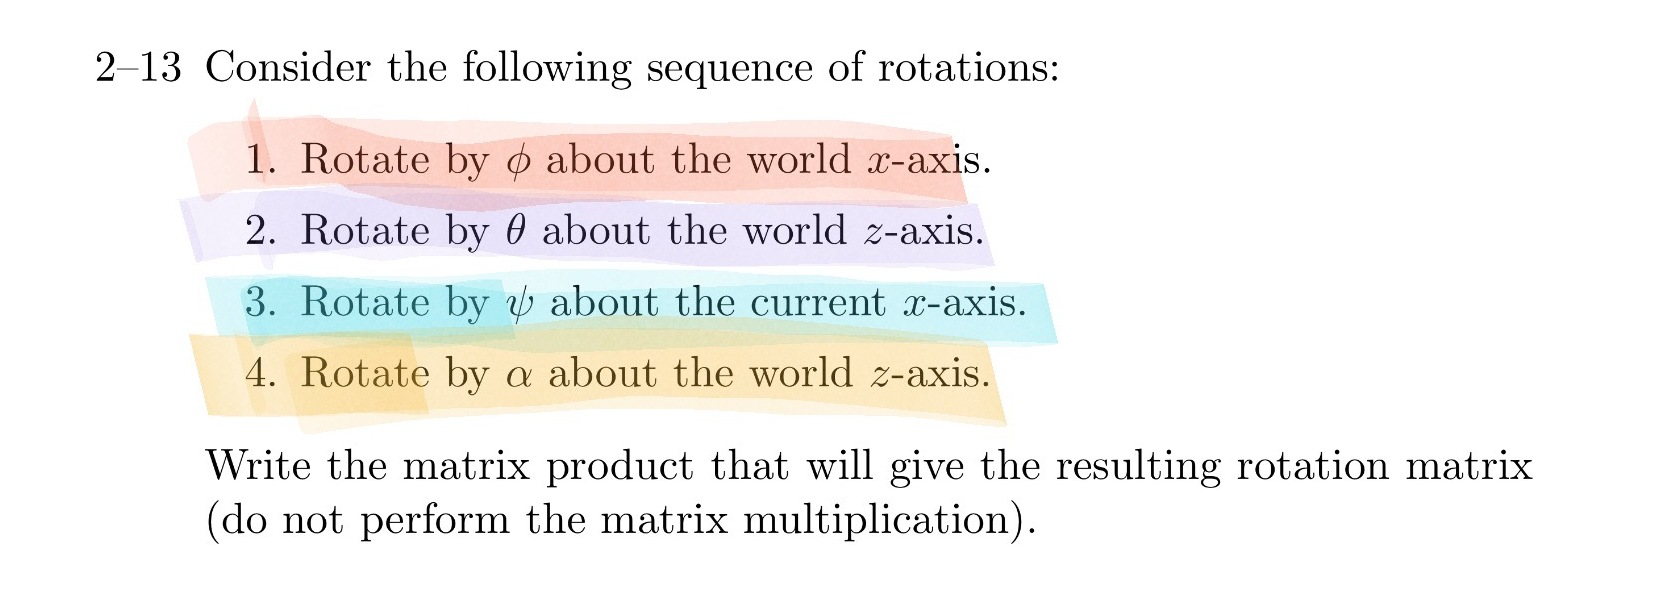

*Figure 3: Problem 2-13 from Robot Modeling and Control, 2nd Edition, page 69*

From here, we can begin to define our rotations, as described from above. We need to take not of the prescribed axis of rotation to define the configuration of the rotation matrix.

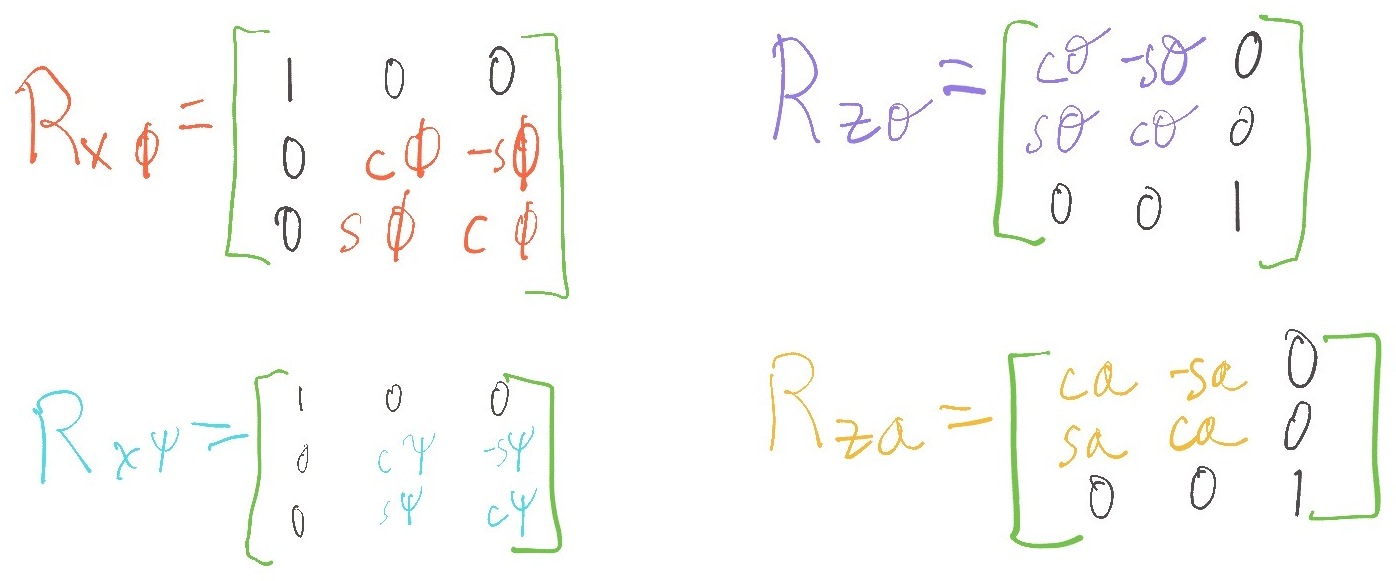

*Figure 4: Rotation matricies defined as per Figure 3*

Once we have defined the rotation matricies, we need to consider how to apply them to a given entity that we wish to rotate. If we consider an entity *E*, which could be another rotation, a point, or a vector, we need to determine how to apply the rotation. This application depends upon whether the rotation is applied as a **current frame** rotation, or a **fixed frame **rotation. In the problem, the fixed frame rotations wold be specified as a rotation around the world axis.

When a **current frame **rotation is called for, we shall be *post-multiplying* the rotation. When a **fixed frame** rotation is called for, we shall be *pre-multiplying *the rotation. Thus, if we take an entity *E*, and apply each rotation as specified, we are compose the rotations as follows:

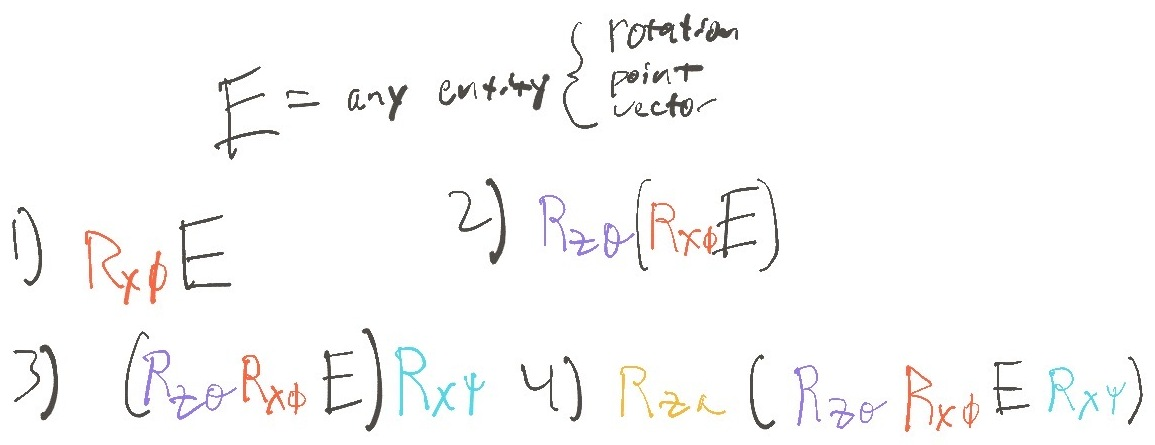

*Figure 5: Composition of multiple rotations as defined in Figure 3*

To illustrate these rotations in the **Results** section, we are applying them to a "coordinate frame", comprised of three vectors drawn from origin with a magnitude only in a singular axis. This represents the coordinate frame in a given space. By applying hte rotation to these coordinate frames, we can then plot the rotated coordinated frame in the plot.

### II-2: Homogenous Transformations

For ease of reading, we shall again present the figure from which we are visually composing our homogenous translations from.

*Figure 6: from Robot Modeling and Control, 2nd edition, page 72*

Determining the displacement is simply following measurements provided against directions of axes. Rotations are a bit more difficult. Two methods could be applied - composing simpler, singular axis rotations, or determing the rotation by looking at the projected change in the original axis relative to the resulting axis. The below figure shows the setup for this approach.

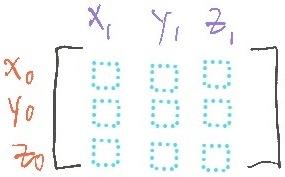

*Figure 7: Configuration of how to project rotation between two coordinate frames*

We did not utilize this approach, however. Instead we opted for composing a rotation from a combination common rotations about a singular axis. From these methods, we built each homogeonous transformation, as demonstrated below.

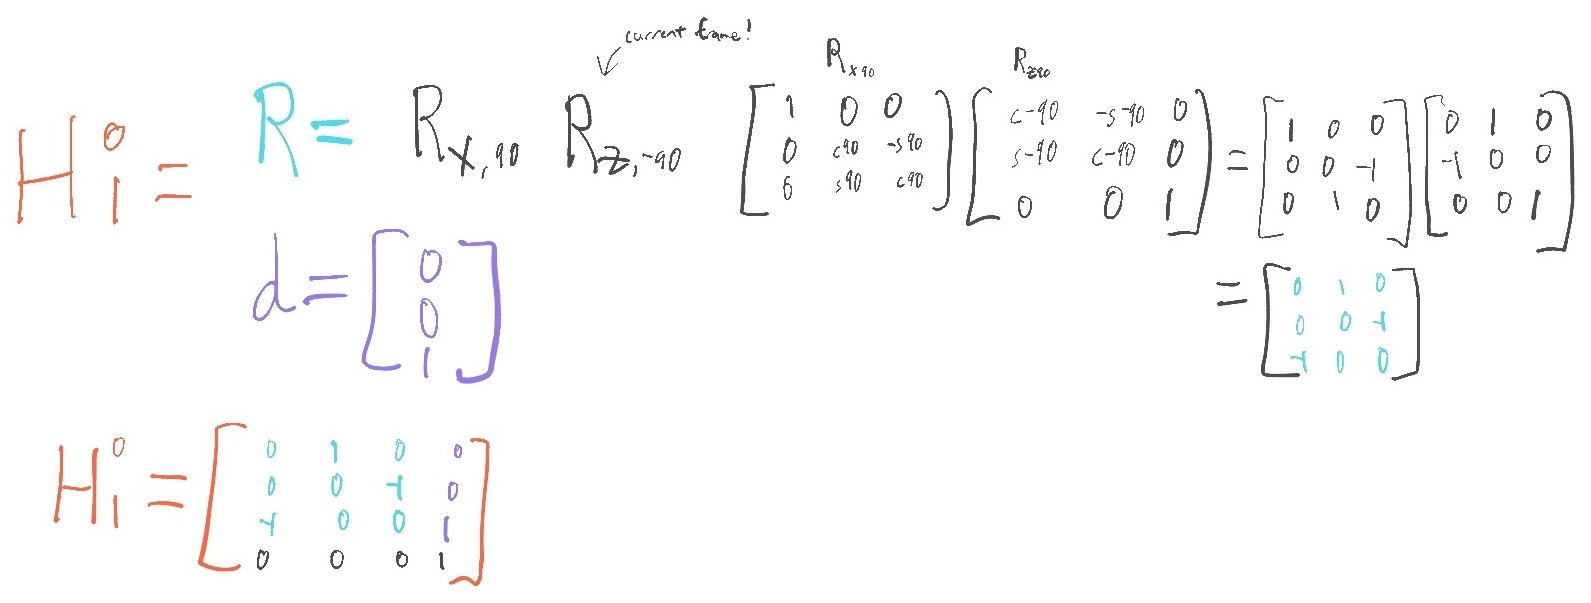

*Figure 8: Determining *$H_1^0$

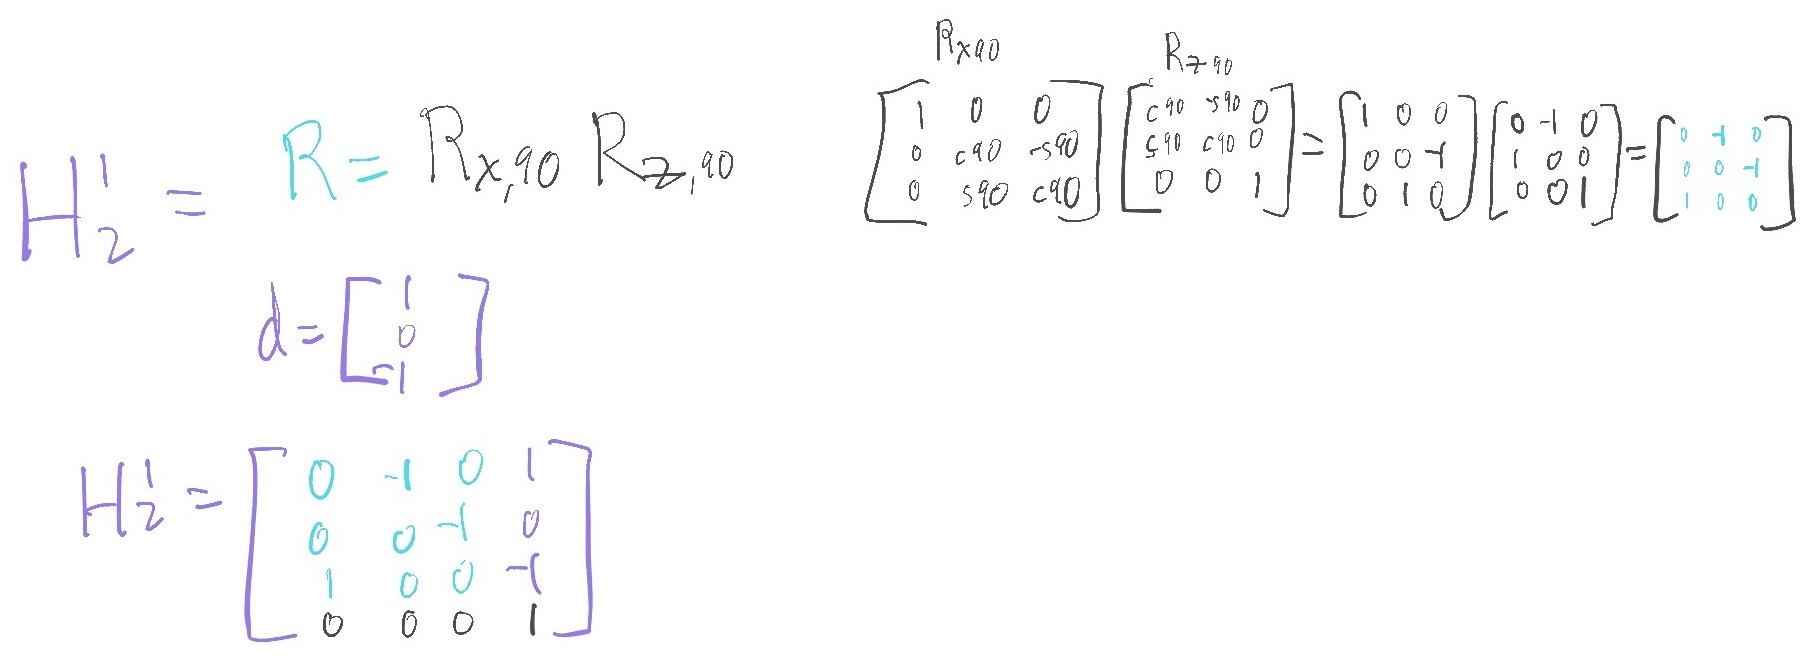

*Figure 9: Determining *$H_2^1$

Since we need to compare the results of our methods of finding $H_2^0$ to our calculated $H_2^0$ from multiplying $H_1^0$ and $H_2^1$, we find $H_2^0$ manually below:

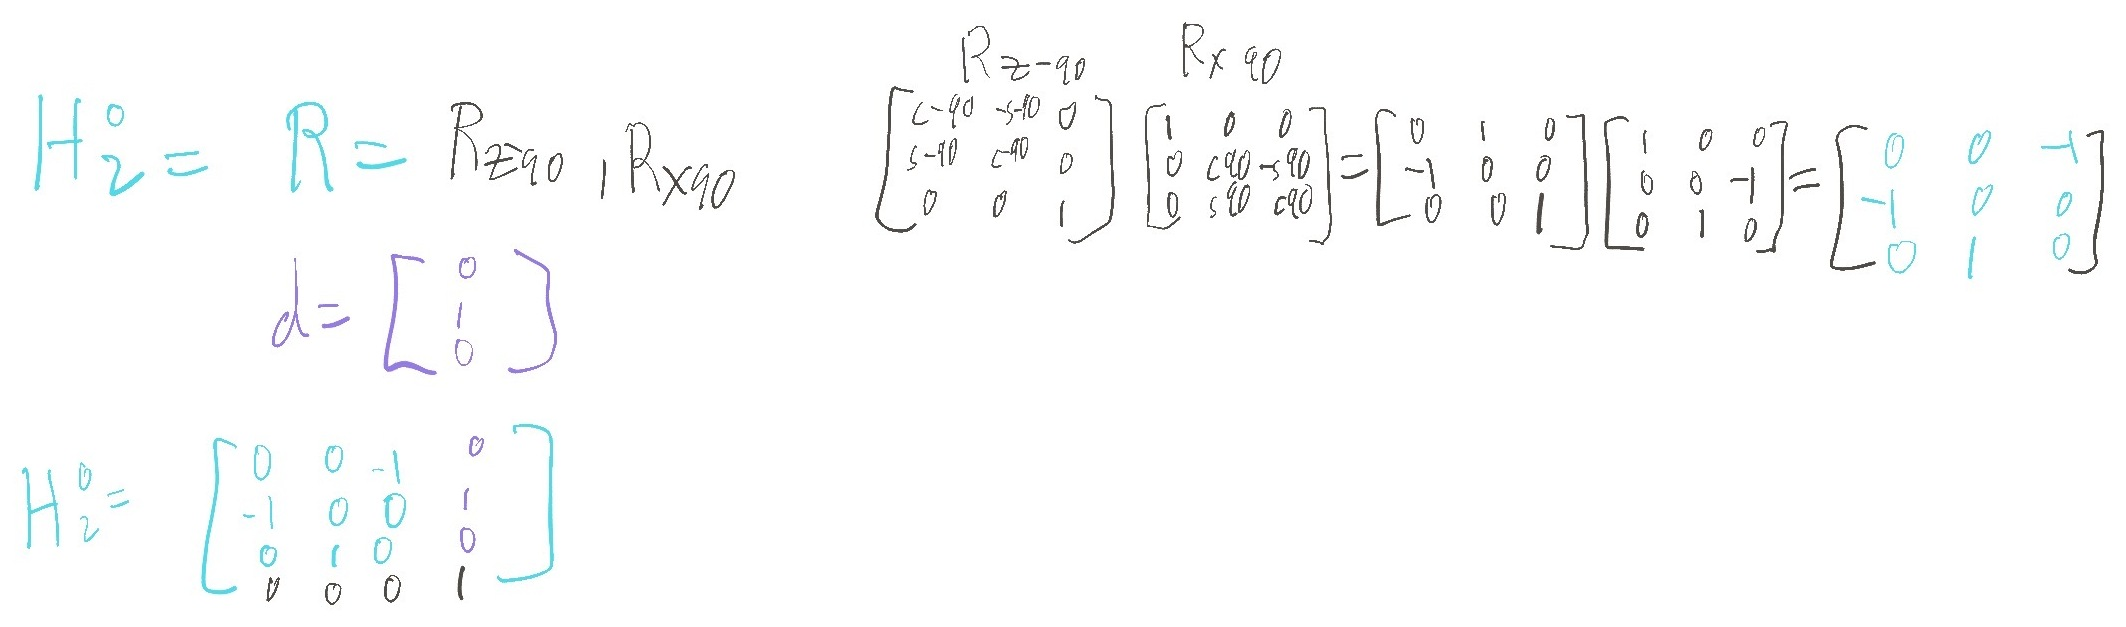

*Figure 10: Determing *$H_2^0$

In the **Results** section, we perform the calculations prescribed and assert whether our calculated $H_2^0$ matches our expectations.

### II-3: Denso HSR Robot

The specified Denso HSR Robot (480mm reach model) has its technical information presented in its catalog. From the catalog, we extract and expand upon this key diagram:

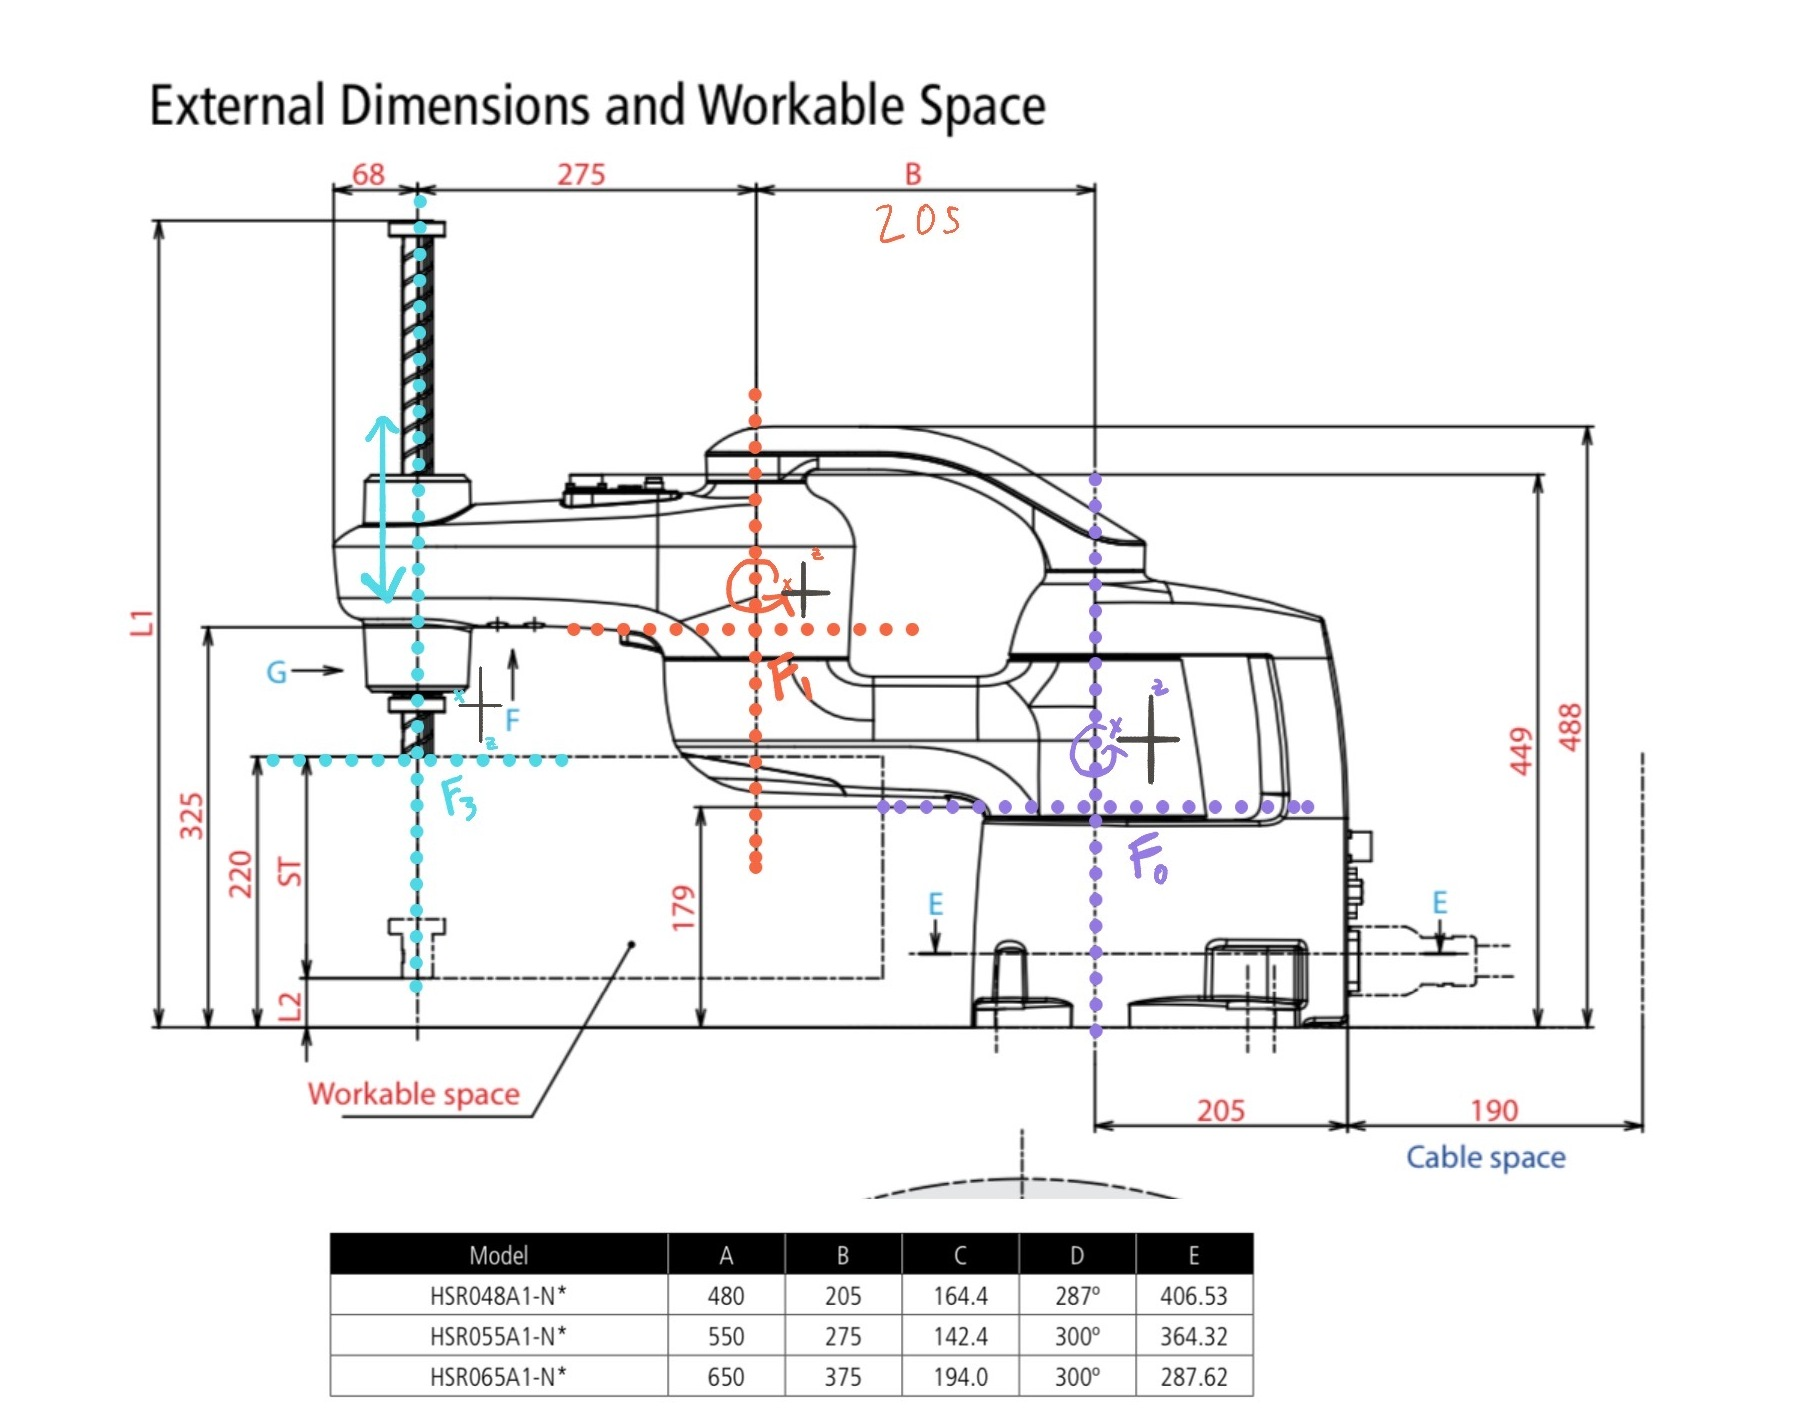

*Figure 11: HSR Denso technical specifications and measurements from the Denso robot arm catalog*

The written dimensions are added as specified for the requested model. The axis are defined to be in line with the given axis of rotation, and line up with a convenient location that has listed measurements. From this point, we can create a simpler model of the arm:

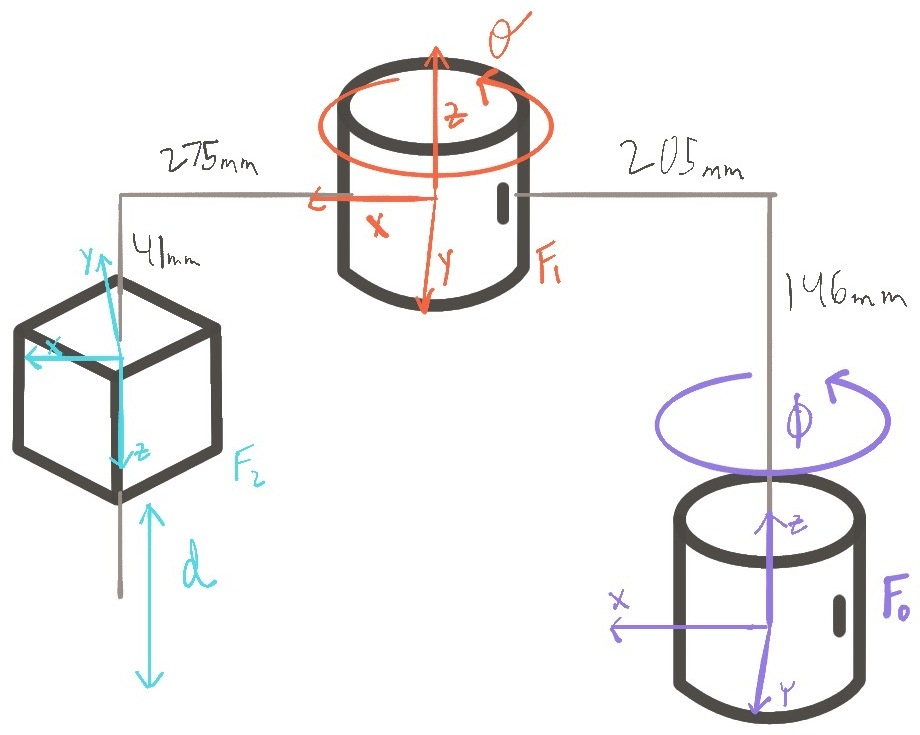

*Figure 12: Simple model and axes for HSR robot arm*

From this model, we can determine our homogenous transformations for each frame. We are denoting our first axis as **frame 0**, our second axis as **frame 1**, and our third axis, our prismatic joint, as **frame 2**. Note that we are treating **frame 0** as our world frame for plotting.

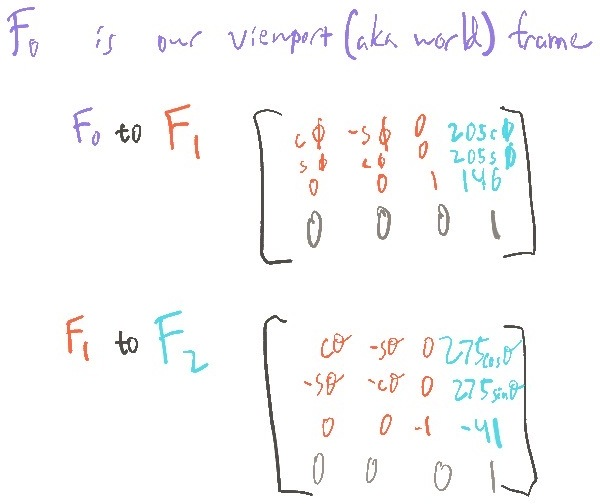

*Figure 13: Homogeonoues transformations for each frame*

We build our homogenous transformations for the model above. The transformations are not static - they will change based on the angle of each prior axis at the given moment. Likewise, this means that a calculated $H_2^0$ would be a function dependent upon $\phi$ and $\theta$.

The rotation between frame 0 and frame 1 is a simple rotation based on $\phi$. From frame 1 to 2, however, we also need to invert the frame to have positive *z* movement move the actuator away from the robot. Thus we compose the rotation matrix as follows:

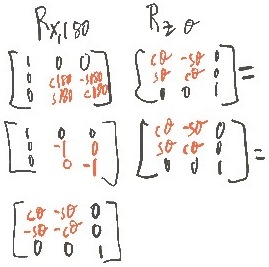

*Figure 14: The resulting matrix is a composition of a 180 degree rotation around the X axis, and a rotation amongst the Z axis by *$\theta$

Once we calculate the homogenous transformations as per the value of $\phi$ and $\theta$ at the moment, we then calculate the homogenous transformation from frame 0 to 2, $H_2^0$.

Since we are plotting within hte context of frame 0 being our world frame, we will need to invert the homogenous transforms to convert the expected location of each coordinate frame and the actuator endpoint back to positions relative to the base frame, our original axis. This inverse is performed by the following approach:

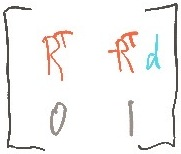

*Figure 15: Inverse homogenous transformation*

## Results

### II-1: Rotation Composition

Choose our sets of angles:

phi =30;
theta = 45;
psi = 60;
alpha = 15;

Here we create our rotation matricies, using the naming convetion of *R_axis_frame_angle*. Here, a*xis* is the given axis the rotation occurs arround, *frame* is whether it occurs relative to the world frame or our current frame (*w* or *c*), and *angle* specifies which angle is being utilized within the rotation.

R_x_w_phi = [ 1 0 0; 0 cosd(phi) -sind(phi); 0 sind(phi) cosd(phi); ];
R_z_w_theta = [ cosd(theta) -sind(theta) 0; sind(theta) cosd(theta) 0; 0 0 1; ];
R_x_c_psi = [ 1 0 0 ; 0 cosd(psi) -sind(psi); 0 sin(psi) cos(psi); ];
R_z_w_alpha = [ cosd(alpha) -sind(alpha) 0; sind(alpha) cosd(alpha) 0; 0 0 1; ];
disp("The resulting rotations matrix after all rotations are performed is:")

The resulting rotations matrix after all rotations are performed is:


R_result = R_z_w_alpha * R_z_w_theta * R_x_w_phi * R_x_c_psi

R_result =     0.5000   -0.5070    0.2371
    0.8660    0.2927   -0.1369
         0   -0.0140   -1.2578


Here we draw a graph of the original entity, and the entity rotated as per the rotations. We utilize the function *draw_coordinate_axes*, which is defined below. We draw two graphs - the first an animation of each rotation, step by step. The second a drawing of the first and final coordinate frame in that process. The initial coordinate frame in each has a red, green, and blue axis for *x*, *y*, and *z* respectively.

 
% Our base coordinate frame is just three vectors from the origin. We
% define it original as three homogenous vectors.
x = [1; 0; 0;];
y = [0; 1; 0;];
z = [0; 0; 1;];
origin = [0; 0; 0;];

figure;
axis equal

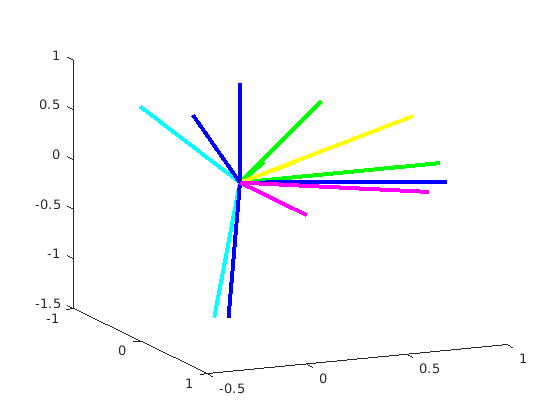

clf;
view([65.931 16.122]);
%draw_axis_plot(x, y, z, 'red', 'green', 'blue');
draw_coordinate_axes(origin, x, y, z, 'red', 'green', 'blue');
pause(1);
R = R_x_w_phi;
%draw_axis_plot(R * x, R * y, R * z, 'magenta', 'yellow', 'cyan');
draw_coordinate_axes(origin, R * x, R * y, R * z, 'magenta', 'yellow', 'cyan');
pause(1);
R = R_z_w_theta * R;
draw_coordinate_axes(origin, R * x, R * y, R * z, 'red', 'green', 'blue');
pause(1);
R = R * R_x_c_psi;
draw_coordinate_axes(origin, R * x, R * y, R * z, 'magenta', 'yellow', 'cyan');
pause(1);
R = R_z_w_alpha * R;
draw_coordinate_axes(origin, R * x, R * y, R * z, 'blue', 'green', 'blue');

In the last figure, we maintain the same starting coordinate frame colors of red, green, and blue, and apply the colors magenta, yellow, and cyan for *x*, *y*, and *z* respectively.

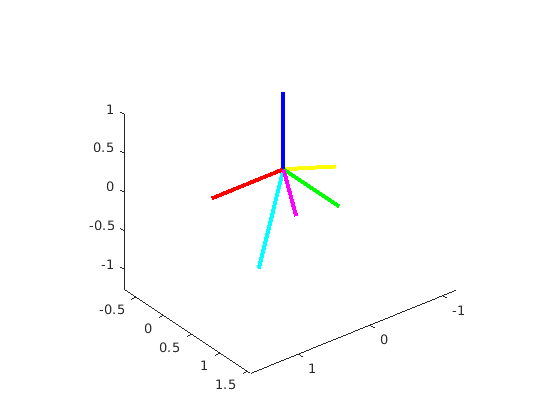

figure
axis equal
draw_coordinate_axes(origin, x, y, z, 'red', 'green', 'blue');
draw_coordinate_axes(origin, R_result * x, R_result * y, R_result * z, 'magenta', 'yellow', 'cyan');
view([141.94 31.38])

### II-2: Homogenous transforms

First, we define our matricies with the naming pattern of H_from_to.

H_0_1 = [ 0 1 0 0; 0 0 -1 0; -1 0 0 1; 0 0 0 1; ];
H_1_2 = [ 0 -1 0 1; 0 0 -1 0; 1 0 0 -1; 0 0 0 1; ];
H_0_2 = [ 0 0 -1 0; -1 0 0 1; 0 1 0 0; 0 0 0 1; ];

Here, we calculate the $H_2^0$ from $H_1^0 *H_2^1$, and then compare the results to our manually composed $H_2^0$.

disp("Comparing H_0_2 and our calculated rotation matricies:")

Comparing H_0_2 and our calculated rotation matricies:


H_0_2

H_0_2 =      0     0    -1     0
    -1     0     0     1
     0     1     0     0
     0     0     0     1


equivalent = H_0_1 * H_1_2

equivalent =      0     0    -1     0
    -1     0     0     1
     0     1     0     0
     0     0     0     1


if isequal(H_0_2, equivalent)
   disp("Rotation matricies are equal!")
else
   disp("Rotation matricies are not equal!") 
end

Rotation matricies are equal!


### Denso HSR Robot Analysis

First we define our starting configuration for the robot arm, and the per-step delta for each axis.

phi = 0;
theta = 0;
stroke = 0;

phi_delta = 1;
theta_delta = 0.5;
stroke_delta = 100 / 180;

Below, you can press "**Run animation**" in order to play the animation of the robot moving according to the above defined initial conditions and per step deltas.

 
% Clean up the prior run, if it occurred
if exist('animated_figure')
    delete(animated_figure)
end

% Initialize our plot
clf
animated_figure = figure;
view([31 33])
view([39 9])
axis equal
grid on
hold on

The following code tracks drawn lines fo the axes.  During each step, we take a step in $\phi$, $\theta$, and our actuator *stroke*. Previous lines to draw coordinate frames are cleared, but previously placed actuator endpoint points are left behind. The new coordinate frame homogenous transformation matricies are calculated based on the new values for $\phi$ and $\theta$. We calculate the location and orientation of each coordinate frame relative to the first frame (our first axis) and draw them into our graph.

We then take the stroke position as a location relative to the frame of of our actuator, which is simply a point at *[0; 0; stroke; 1;]*. We convert this to the first frame's coordinate reference by using the inverse of our calculated homogenous transformation from frame 0 to 2.

The inverse transforms are performed in a function *inverse_transform*, defined below.

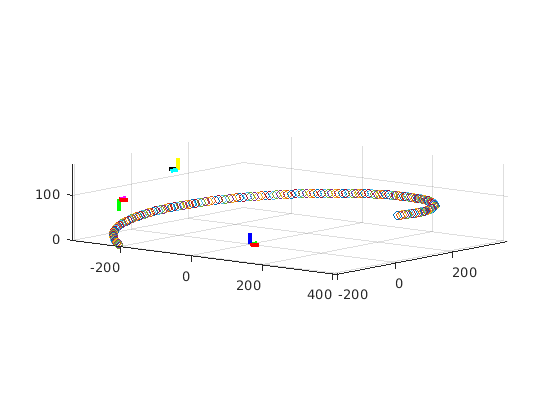

lines = [];
for step = 1:180
   phi = phi + phi_delta;
   theta = theta + theta_delta;
   stroke = stroke + stroke_delta;
   
   H_0_1 = [ cosd(phi) -sind(phi) 0 205*cosd(phi); sind(phi) cosd(phi) 0 205*sind(phi); 0 0 1 146; 0 0 0 1; ];
   H_1_2 = [ cosd(theta) -sind(theta) 0 205*cosd(theta); -sind(theta) -cosd(theta) 0 205*sind(theta); 0 0 -1 -41; 0 0 0 1; ];
   % Get our tip to  tip rotation
   H_0_2 = H_0_1 * H_1_2;
   
   % We actually need the inverses of these transformations, as we're going
   % to want to convert their coordinates (such as their origin) back to
   % our original frame 0. So we'll grab inverses of what we need - H_2_0
   % and H_1_0.
   H_1_0 = inverse_transform(H_0_1);
   H_2_0 = inverse_transform(H_0_2);

   % If they've been drawn, clear the previous lines making up the axes
   for index = 1:length(lines)
       delete(lines(index));
   end
   lines = [];
   
   % Draw each coordinate frame
   % Our base frame doesn't move relative to itself
   origin = [0; 0; 0; 1;];
   x = [25; 0; 0; 1;];
   y = [0; 25; 0; 1;];
   z = [0; 0; 25; 1;];
   
   % Draw the our first axis, which is also our world coordinate frame
   [x_line, y_line, z_line] = draw_coordinate_axes(origin, x, y, z, "red", "green", "blue");
   lines(end+1) = x_line;
   lines(end+1) = y_line;
   lines(end+1) = z_line;
   
   % Transform it to the resultant vector of the next axis
   [x_line, y_line, z_line] = draw_coordinate_axes(H_1_0 * origin, H_1_0 * x, H_1_0 * y, H_1_0 * z, "black", "cyan", "yellow");
   lines(end+1) = x_line;
   lines(end+1) = y_line;
   lines(end+1) = z_line;
   
   % Transform for the third axis uses H_0_2 since we're drawing relative
   % to our first 0th frame.
   [x_line, y_line, z_line] = draw_coordinate_axes(H_2_0 * origin, H_2_0 * x, H_2_0 * y, H_2_0 * z, "magenta", "red", "green");
   lines(end+1) = x_line;
   lines(end+1) = y_line;
   lines(end+1) = z_line;
   
   % Now we are going to draw the point of where the actuator is
   % Our point relative to the third frame:
   actuator_endpoint = [0; 0; stroke; 1;];
   % Now convert it to be relative to the frame of our first axis.
   actuator_endpoint_0 = H_2_0 * actuator_endpoint;
   
   plot3(actuator_endpoint_0(1), actuator_endpoint_0(2), actuator_endpoint_0(3), 'o')
   
   pause(0.01)
    
   
end
hold off

### Functions

In MATLAB, all functions are required to be placed at the end of a given file. This function to draw coordinate axes in a given figure is used throughout the code above, and is defined below.

function [x_line, y_line, z_line] = draw_coordinate_axes(origin, to_x, to_y, to_z, x_color, y_color, z_color)    
    x_line = line('XData', [origin(1) to_x(1)], 'YData', [origin(2) to_x(2)], 'ZData', [origin(3) to_x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) to_y(1)], 'YData', [origin(2) to_y(2)], 'ZData', [origin(3) to_y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) to_z(1)], 'YData', [origin(2) to_z(2)], 'ZData', [origin(3) to_z(3)], 'Color', z_color, 'LineWidth', 3);
end

This function takes a homogenous transform and inverts it in a manner as described in *Figure 15*.

function out_transform = inverse_transform(in_transform)
   % First we get our rotation matrix and displacement from our homogenous
   % transform
   rotation = in_transform(1:3, 1:3);
   displacement = in_transform(1:3, 4);
   
   % The rotation inverse is merely the transpose
   rotation_inverse = transpose(rotation);
   % The displacement inverse is the negative transpose multiplied by the
   % displacement
   displacement_inverse = -rotation_inverse * displacement;
   out_transform = [ rotation_inverse(1) rotation_inverse(2) rotation_inverse(3) displacement_inverse(1); rotation_inverse(4) rotation_inverse(5) rotation_inverse(6) displacement_inverse(2); rotation_inverse(7) rotation_inverse(8) rotation_inverse(9) displacement_inverse(3); 0 0 0 1; ];

end

## Discussion

This assignment's aim was to demonstrate an understanding of rigid motions for robotics - specifically rotations, their compositions, and work with homogenous transformations. To accomplish this, we applied these concepts to three problems.

In our first problem, we explored the composition rules for rotation matricies based on their frame of rotation. The rotation matricies were defined per the simple singular-axis rotation as specified, and then either *pre-* or *post-* multiplied based on the frame of rotation (fixed and current frame, respectively).

Our second problem had us compose homogenous transformations based on *Figure 1*. We then confirmed that our created $H_2^0 \;$homogenous transformation matches one calculated by $H_1^0 *H_2^1$.

In our third problem, we are posed a more application-focused question - can we properly analyze the movement and positioning of a real industrial robot arm? We are given a specified model of a Denso HSR SCARA robot (*RRP,* or revolute-revolute-prismatic joint arm). The arm is an excellent choice for many high speed pick and place operations in industrial and commercial settings.

Once we look at the arm in the provided sales catalog, we derive a model of the arm based on specifications. From this model we can generate homogenous transforms for each axis of the robot and plot the path of the actuator as the robot moves in a question-defined path.

This problem applies much of the material learned throughout the week and our readngs. We could apply similra techniques to other robotic arms in order to determine if their range of movement would be suitable for a given application.

## Citations

- SPONG, M. W., HUTCHINSON, S., & VIDYASAGAR, M. (2020). *Robot modeling and control*. *2nd edition* Hoboken, NJ, John Wiley & Sons. 

- Denso Robotics Catalog [https://www.revbase.com/tt/sl.ashx?z=78fb9fde&DataID=2455047&ft=1](https://www.revbase.com/tt/sl.ashx?z=78fb9fde&DataID=2455047&ft=1)* Pages 30-31 Access Date 02/10/2020*